% section 1

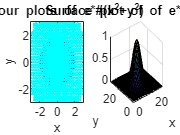

% Gradient 1
clc                                 % Clear command window
clear variables                     % Erase all variables
close all                           % Close all windows
v = -3:0.2:3;
[x,y] = meshgrid(v);
z = exp(-(x.*x+y.^2));
[px,py] = gradient(z,0.2,0.2);
subplot(1,2,1)
contour(v,v,z,20,'LineWidth',3);
hold on;
quiver(v,v,px,py,'LineWidth',2,'Color','cyan');
hold off;
xlabel('x');
ylabel('y');
title('contour plots of e*#(x^2+y^2)');
subplot(1,2,2)
surf(z)
xlabel('x');
ylabel('y');
title('Surface plot of of e*#(x^2+y^2)');

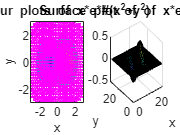

 % Gradient 2
clc                                 % Clear command window
clear variables                     % Erase all variables
close all                           % Close all windows
v = -3:0.2:3;
[x,y] = meshgrid(v);
z = x.*exp(-(x.^2+y.^2));
[px,py] = gradient(z,0.2,0.2);
subplot(1,2,1)
contour(v,v,z,20,'Linewidth',3);
hold on;
quiver(v,v,px,py,'Linewidth',2,'color','magenta');
hold off
xlabel('x');
ylabel('y');
title('contour plots of x*e*#(x^2+y^2)');
subplot(1,2,2)
surf(z)
xlabel('x');
ylabel('y');
title('Surface plot of of x*e*#(x^2+y^2)');

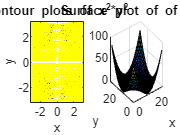

% Gradiant 3
clc                                 % Clear command window
clear variables                     % Erase all variables
close all                           % Close all windows
v = -3:0.2:3;
[x,y] = meshgrid(v);
z = ((x.*x).*(y.*y));
[px,py] = gradient(z,0.2,0.2);
subplot(1,2,1)
contour(v,v,z,20,'Linewidth',3);
hold on;
quiver(v,v,px,py,'Linewidth',2,'color','yellow');
hold off
xlabel('x');
ylabel('y');
title('contour plots of x^2*y^2');
subplot(1,2,2)
surf(z)
xlabel('x');
ylabel('y');
title('Surface plot of of x^2*y^2');

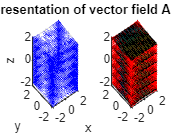

% Divergence 1
clc                                 % Clear command window
clear variables                     % Erase all variables
close all                           % Close all windows
v=-2:0.2:2;
[x,y,z]=meshgrid(v);
fx= x.*z;
fy= -y.^2;
fz= 2*x.^2.*y;
div=divergence(x,y,z,fx,fy,fz);
subplot(1,2,1)
quiver3(x,y,z,fx,fy,fz,'color','blue');
title('Arrow representation of vector field A')
xlabel('x')
ylabel('y')
zlabel('z')
subplot(1,2,2);
quiver3(x,y,z,fx,fy,fz,'color','red');
hold on
for i=1:round(length(x)/5):length(x)
surf(x(:,:,i),y(:,:,i),z(:,:,i),div(:,:,i))
end

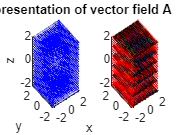

% Divergence 2
clc                                 % Clear command window
clear variables                     % Erase all variables
close all                           % Close all windows
v=-2:0.2:2;
[x,y,z]=meshgrid(v);
fx= x.^3;
fy= y;
fz= z;
div=divergence(x,y,z,fx,fy,fz);
subplot(1,2,1)
quiver3(x,y,z,fx,fy,fz,'color','blue');
title('Arrow representation of vector field A')
xlabel('x')
ylabel('y')
zlabel('z')
subplot(1,2,2);
quiver3(x,y,z,fx,fy,fz,'color','red');
hold on
for i=1:round(length(x)/5):length(x)
surf(x(:,:,i),y(:,:,i),z(:,:,i),div(:,:,i))
end

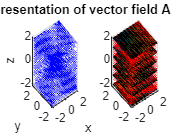

% Divergence 3
clc                                 % Clear command window
clear variables                     % Erase all variables
close all                           % Close all windows
v=-2:0.2:2;
[x,y,z]=meshgrid(v);
fx= x.^2.*y;
fy= -y.^2.*z;
fz= z.^2.*x;
div=divergence(x,y,z,fx,fy,fz);
subplot(1,2,1)
quiver3(x,y,z,fx,fy,fz,'color','blue');
title('Arrow representation of vector field A')
xlabel('x')
ylabel('y')
zlabel('z')
subplot(1,2,2);
quiver3(x,y,z,fx,fy,fz,'color','red');
hold on
for i=1:round(length(x)/5):length(x)
surf(x(:,:,i),y(:,:,i),z(:,:,i),div(:,:,i))
end

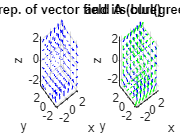

% Curl 1
clc                                 % Clear command window
clear variables                     % Erase all variables
close all                           % Close all windows
v=-2:0.8:2;
[x,y,z]=meshgrid(v);
fx=y.*y;
fy=2* (x.*y)+z.^2;
fz=2* (y.*z);
[curlx,curly,curlz]=curl(x,y,z,fx,fy,fz);
subplot(1,2,1)
quiver3(x,y,z,fx,fy,fz,'color','blue');
title('Arrow rep. of vector field A (blue)')
xlabel('x')
ylabel('y')
zlabel('z')
subplot(1,2,2)
quiver3(x,y,z,fx,fy,fz,'color','blue');
hold on;
quiver3(x,y,z,curlx,curly,curlz,'color','green')
title(' and its curl(green)')
xlabel('x')
ylabel('y')
zlabel('z')

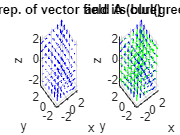

% Curl 2
clc                                 % Clear command window
clear variables                     % Erase all variables
close all                           % Close all windows
v=-2:0.8:2;
[x,y,z]=meshgrid(v);
fx= x.*y;
fy= y.*z;
fz= z.*x;
[curlx,curly,curlz]=curl(x,y,z,fx,fy,fz);
subplot(1,2,1)
quiver3(x,y,z,fx,fy,fz,'color','blue');
title('Arrow rep. of vector field A (blue)')
xlabel('x')
ylabel('y')
zlabel('z')
subplot(1,2,2)
quiver3(x,y,z,fx,fy,fz,'color','blue');
hold on;
quiver3(x,y,z,curlx,curly,curlz,'color','green')
title(' and its curl(green)')
xlabel('x')
ylabel('y')
zlabel('z')

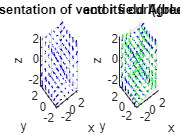

% Curl 3
clc                                 % Clear command window
clear variables                     % Erase all variables
close all                           % Close all windows
v=-2:0.8:2;
[x,y,z]=meshgrid(v);
fx= x.*y.^2;
fy= -y.*z.^2;
fz= z.*x.^2;
[curlx,curly,curlz]=curl(x,y,z,fx,fy,fz);
subplot(1,2,1)
quiver3(x,y,z,fx,fy,fz,'color','blue');
title('Arrow representation of vector field A(blue)')
xlabel('x')
ylabel('y')
zlabel('z')
subplot(1,2,2)
quiver3(x,y,z,fx,fy,fz,'color','blue');
hold on;
quiver3(x,y,z,curlx,curly,curlz,'color','green')
title('and its curl(green)')
xlabel('x')
ylabel('y')
zlabel('z')

% section 2

% section 3

% section 4

E0 = [18, 20, 22, 24, 26, 28, 30, 32, 34, 36, 38, 40, 42, 44, 46];
H0 = [2, 2.1, 2.2, 2.3, 2.4, 2.5, 2.6, 2.7, 2.8, 2.9, 3, 3.1, 3.2, 3.3, 3.4];
impedance = sum(E0./H0)/15;
disp("The average value of impedance is:");

The average value of impedance is:


disp(impedance);

   11.6331



% section 5

clc                                 % Clear command window
clear variables                     % Erase all variables
close all                           % Close all windows
A = [1, 2, 1];
B = [2, 1, 2];
C = [1, 3, 4];
Volume = abs(dot(A,cross(B,C)));
disp("The volume of the parallelepiped formed by three vectors A, B and C is:");

The volume of the parallelepiped formed by three vectors A, B and C is:


disp(Volume);

     9

